Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi

Dipartimento di Ingegneria Industriale

Universita` degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

kappa = 1000;
c     = 10;
alpha = 10; % degree
DAE = BiralDAE2( kappa, c, alpha );

#### Initialize the solver class

solver = DAE3TaylorSolver();
solver.setDAE( DAE );

#### Initialize the range where solution is computed and initial conditions

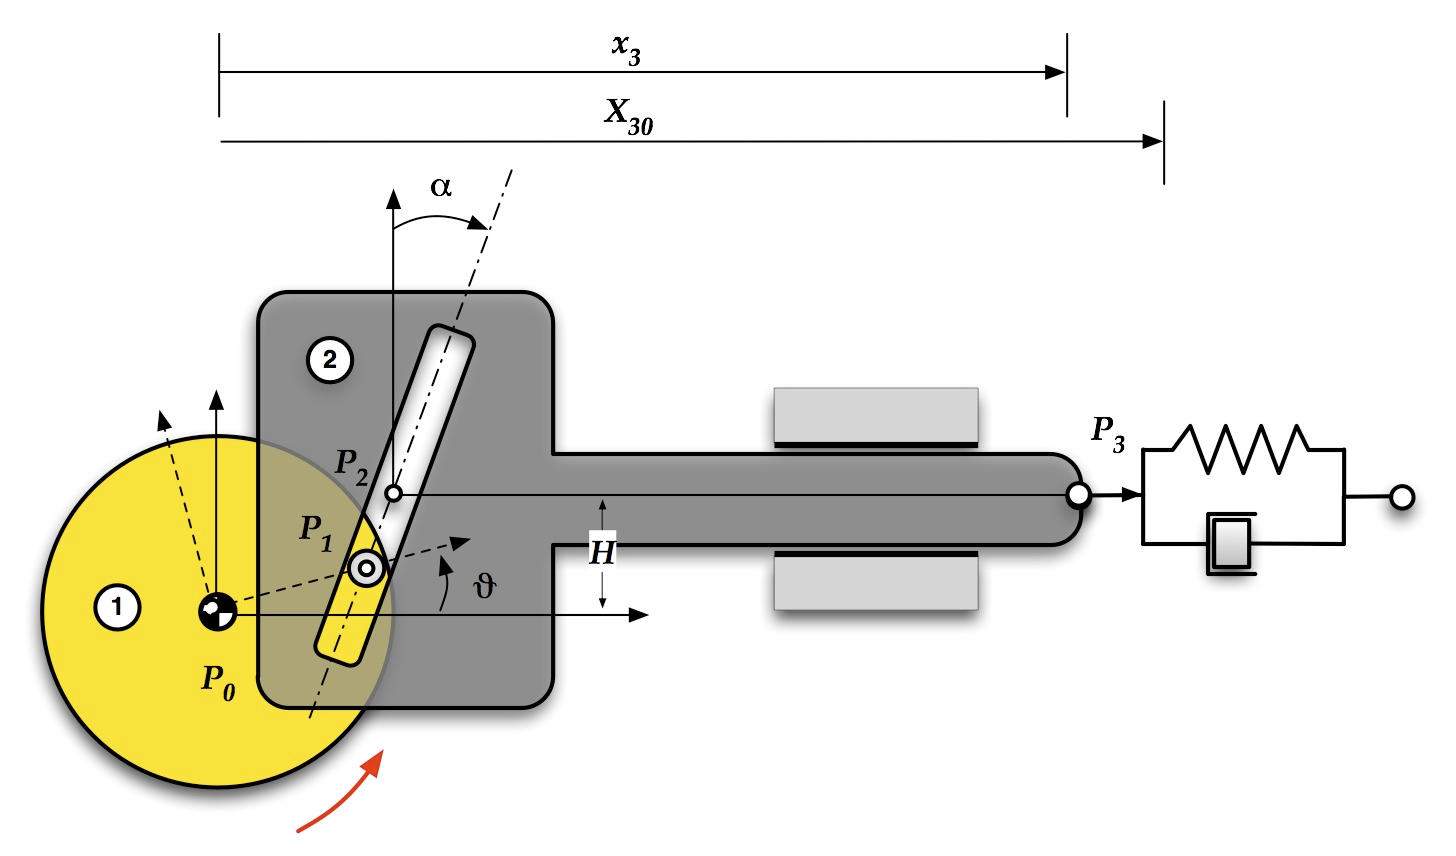

theta10 = 0;
x20     = DAE.theta_to_x2(theta10);
omega10 = 0;
u20     = 0;

p0 = [ theta10; x20 ];
v0 = [ omega10; u20 ];

#### Advance the DAE (using not stabilized index-1 DAE)

DT = 0.025;
T  = 1;

tt  = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
[p, v ] = solver.advance_simple( tt,  p0, v0 );
[p1,v1] = solver.advance_simple( tt1, p0, v0 );
[p2,v2] = solver.advance_simple( tt2, p0, v0 );

#### Plot solution

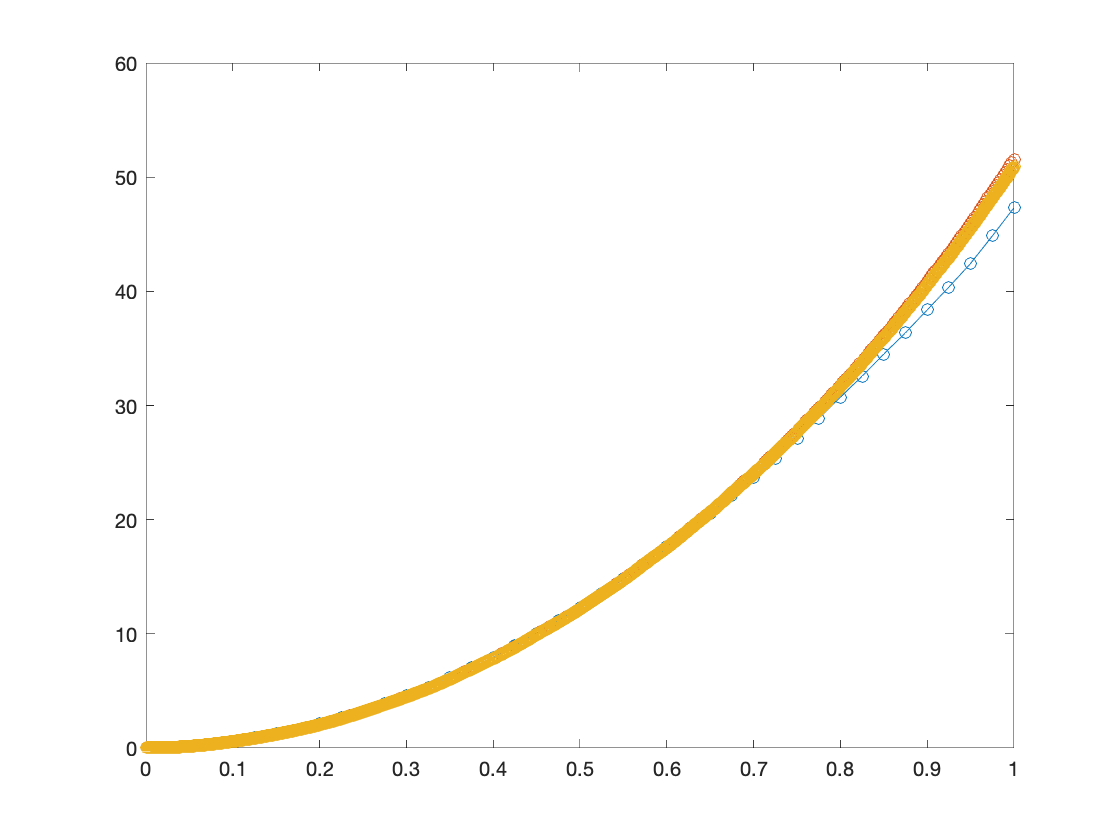

figure();
plot( tt,  p(1,:),  'o-', 'Linewidth', 0.2);
hold on;
plot( tt1, p1(1,:), 'o-', 'Linewidth', 0.2);
plot( tt2, p2(1,:), 'o-', 'Linewidth', 0.2);
hold off

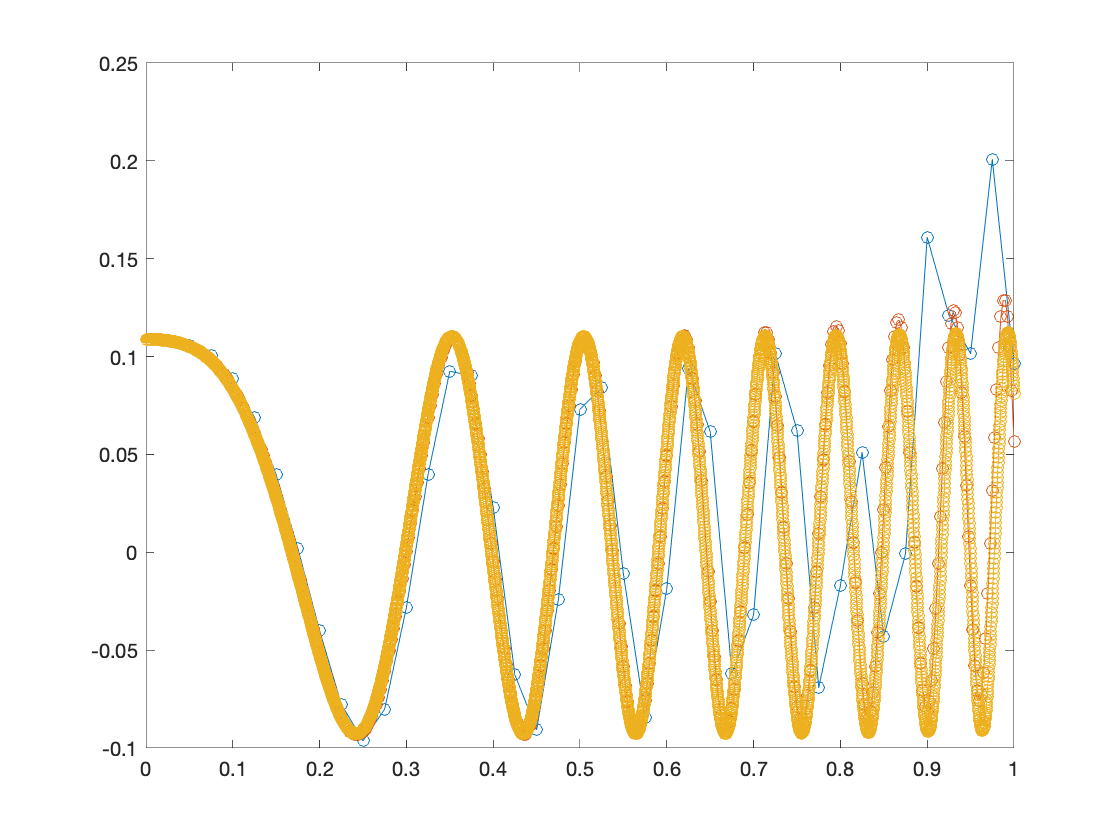


figure();
plot( tt,  p(2,:),  'o-', 'Linewidth', 0.2);
hold on;
plot( tt1, p1(2,:), 'o-', 'Linewidth', 0.2);
plot( tt2, p2(2,:), 'o-', 'Linewidth', 0.2);
hold off

#### Plot animation

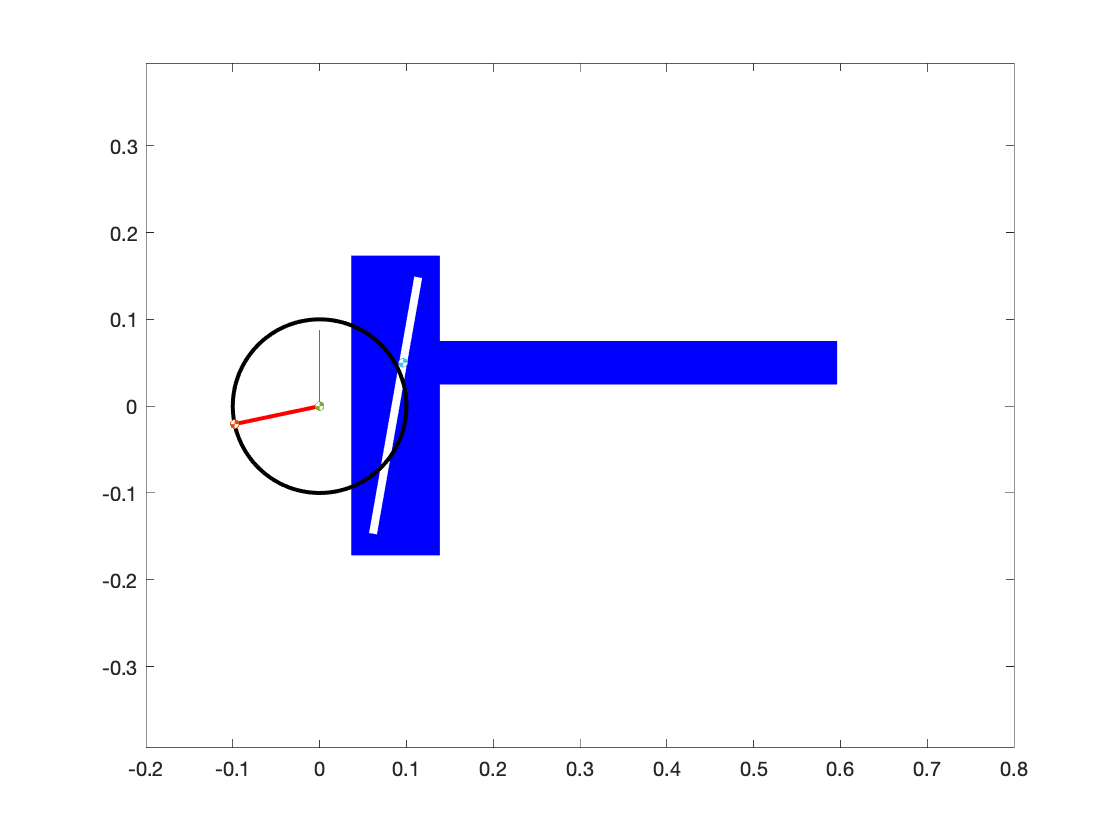

figure();
for k=1:size(p,2)
  DAE.plot(p(:,k));
  axis equal
  drawnow;
end

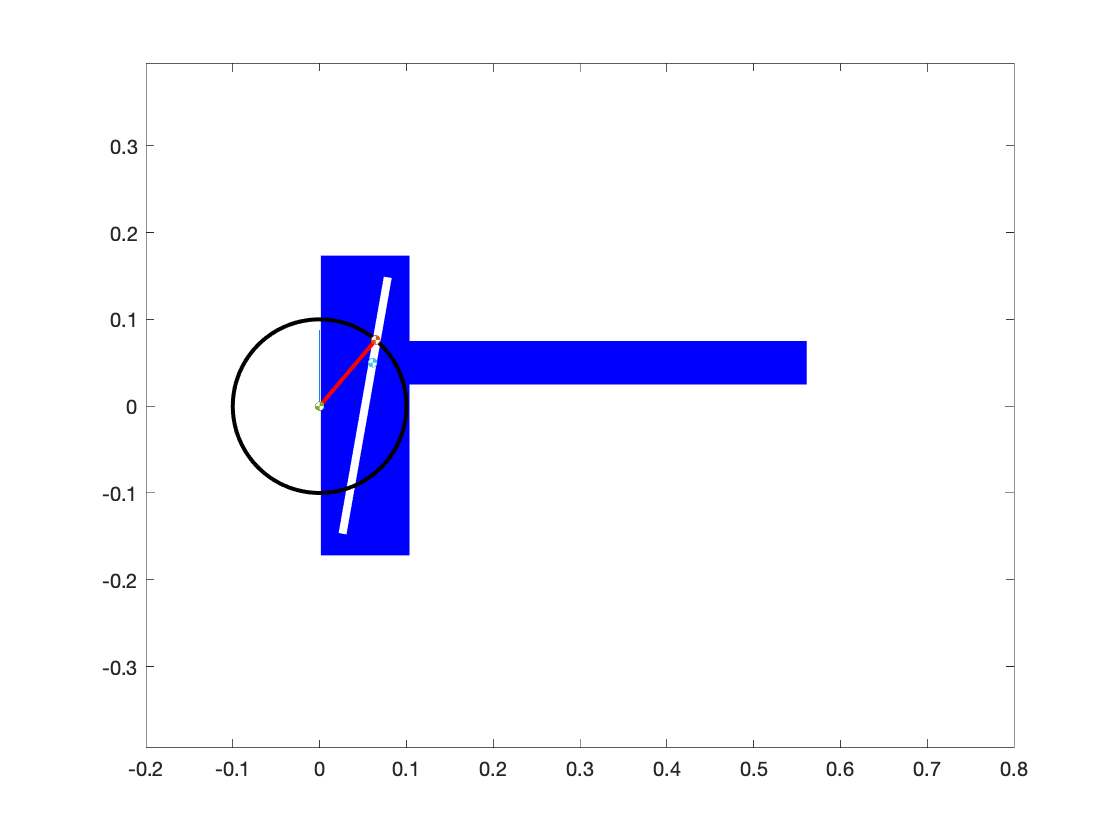

figure();
for k=1:10:size(p1,2)
  DAE.plot(p1(:,k));
  axis equal
  drawnow;
end

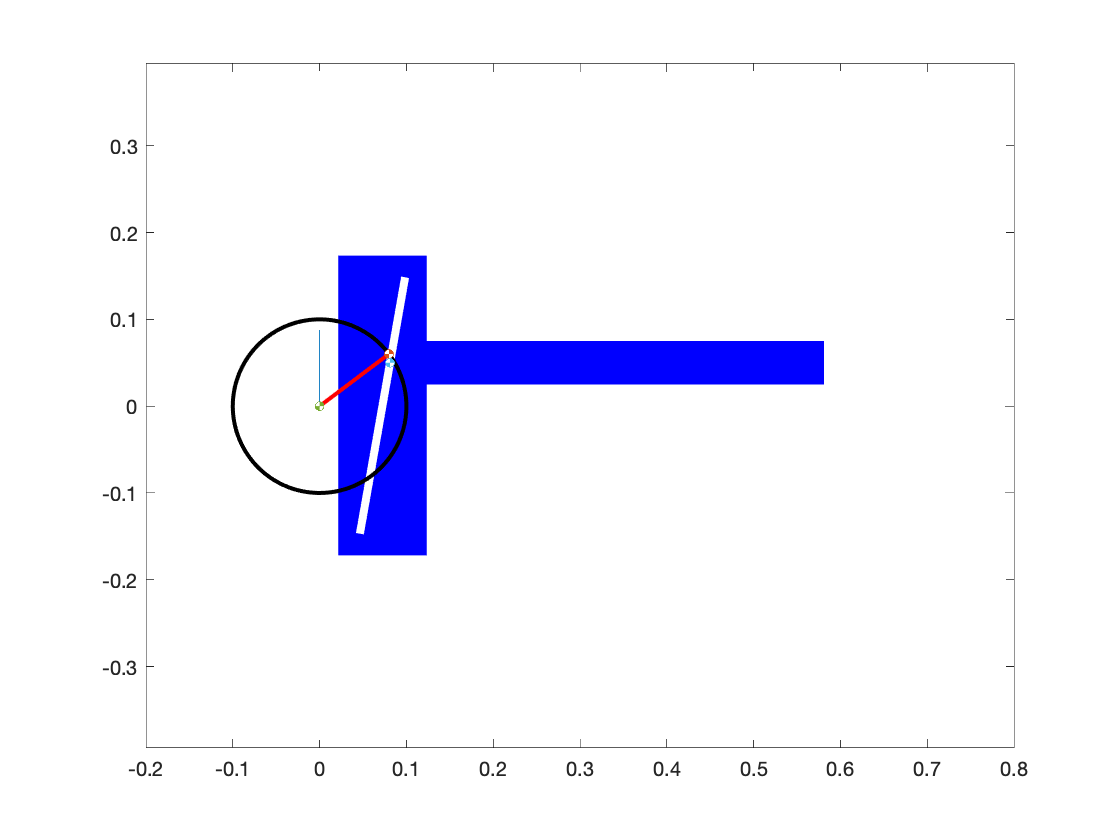

figure();
for k=1:20:size(p2,2)
  DAE.plot(p2(:,k));
  axis equal
  drawnow;
end

#### Advance the DAE (using stabilized index-1 DAE)

DT = 0.025;
T  = 1;

eta   = 0.5;
omega = 10;

tt  = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
[p, v, lambda ] = solver.advance_Baumgarte( tt,  p0, v0, eta, omega );
[p1,v1,lambda1] = solver.advance_Baumgarte( tt1, p0, v0, eta, omega );
[p2,v2,lambda2] = solver.advance_Baumgarte( tt2, p0, v0, eta, omega );

#### Plot solution

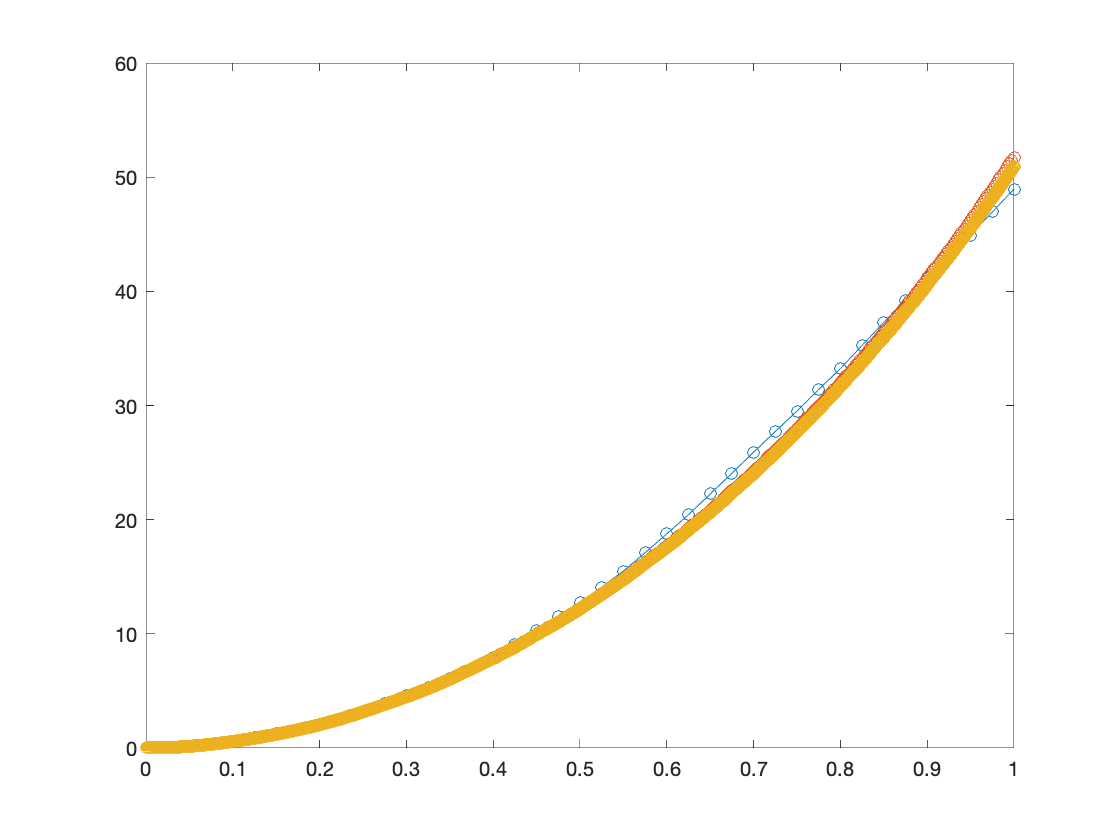

figure();
plot( tt,  p(1,:),  'o-', 'Linewidth', 0.2);
hold on;
plot( tt1, p1(1,:), 'o-', 'Linewidth', 0.2);
plot( tt2, p2(1,:), 'o-', 'Linewidth', 0.2);
hold off

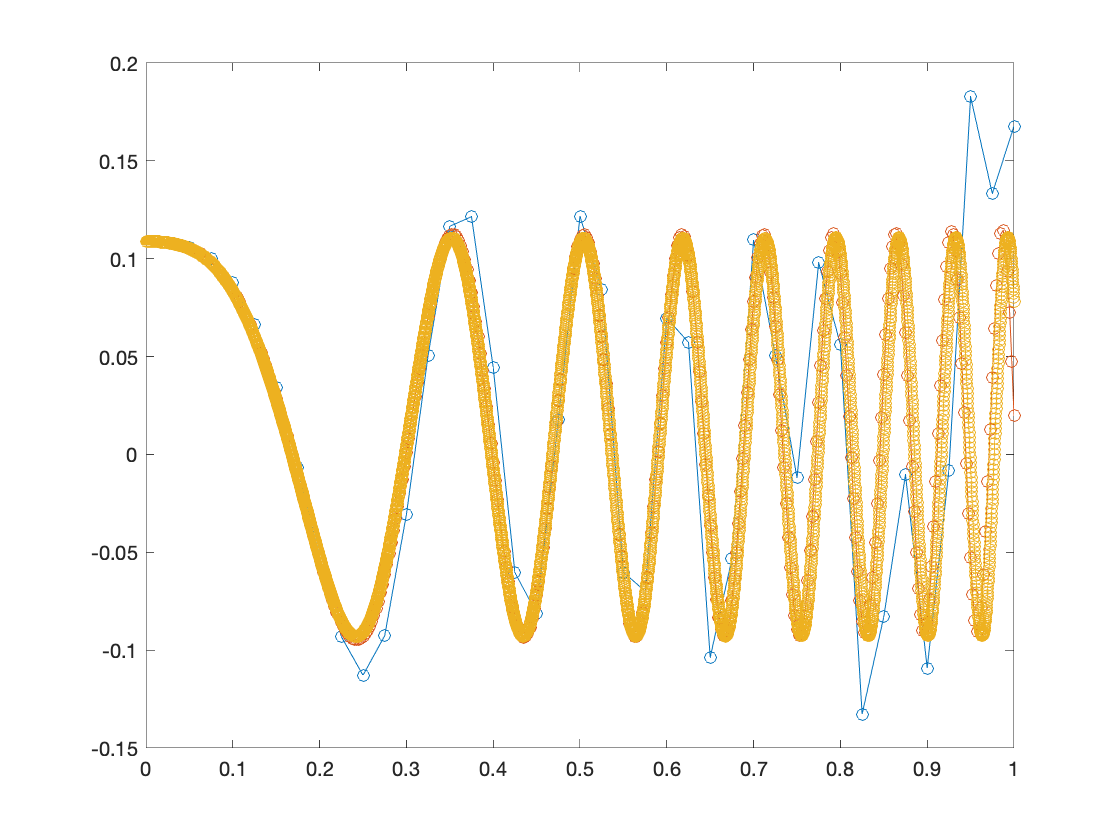

figure();
plot( tt,  p(2,:),  'o-', 'Linewidth', 0.2);
hold on;
plot( tt1, p1(2,:), 'o-', 'Linewidth', 0.2);
plot( tt2, p2(2,:), 'o-', 'Linewidth', 0.2);
hold off

#### Plot animation

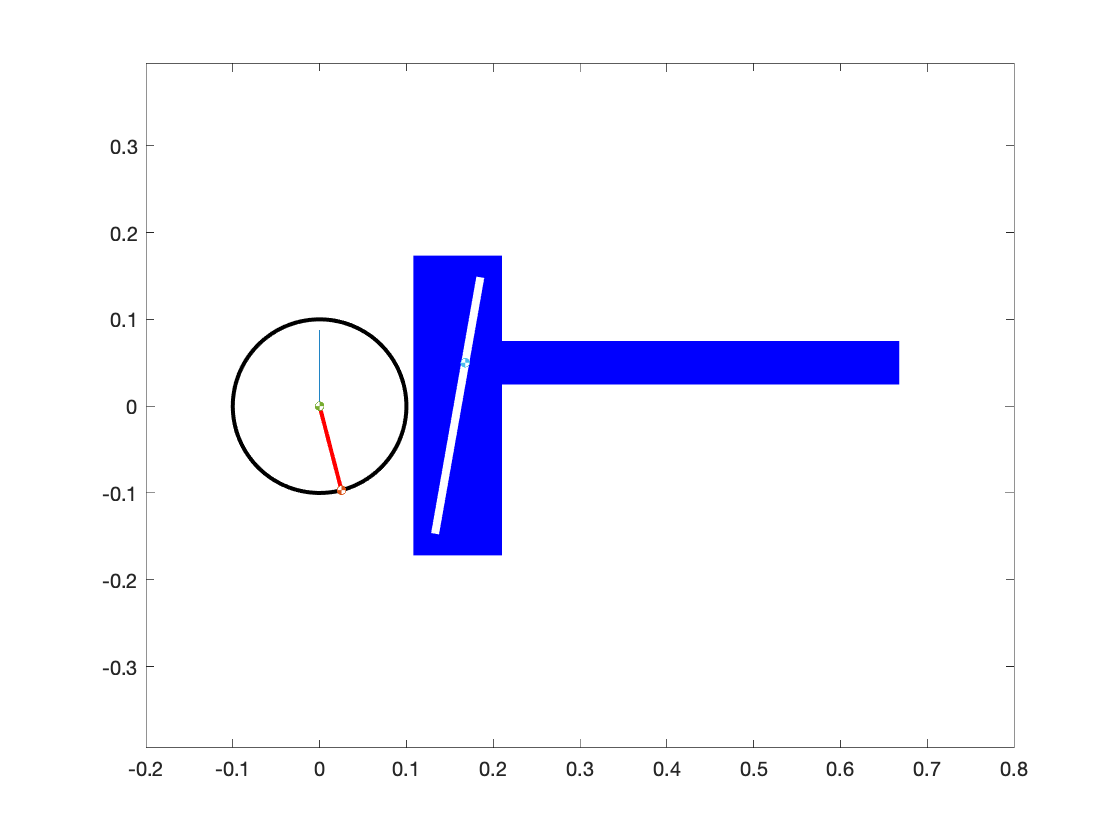

figure();
for k=1:size(p,2)
  DAE.plot(p(:,k));
  axis equal
  drawnow;
end

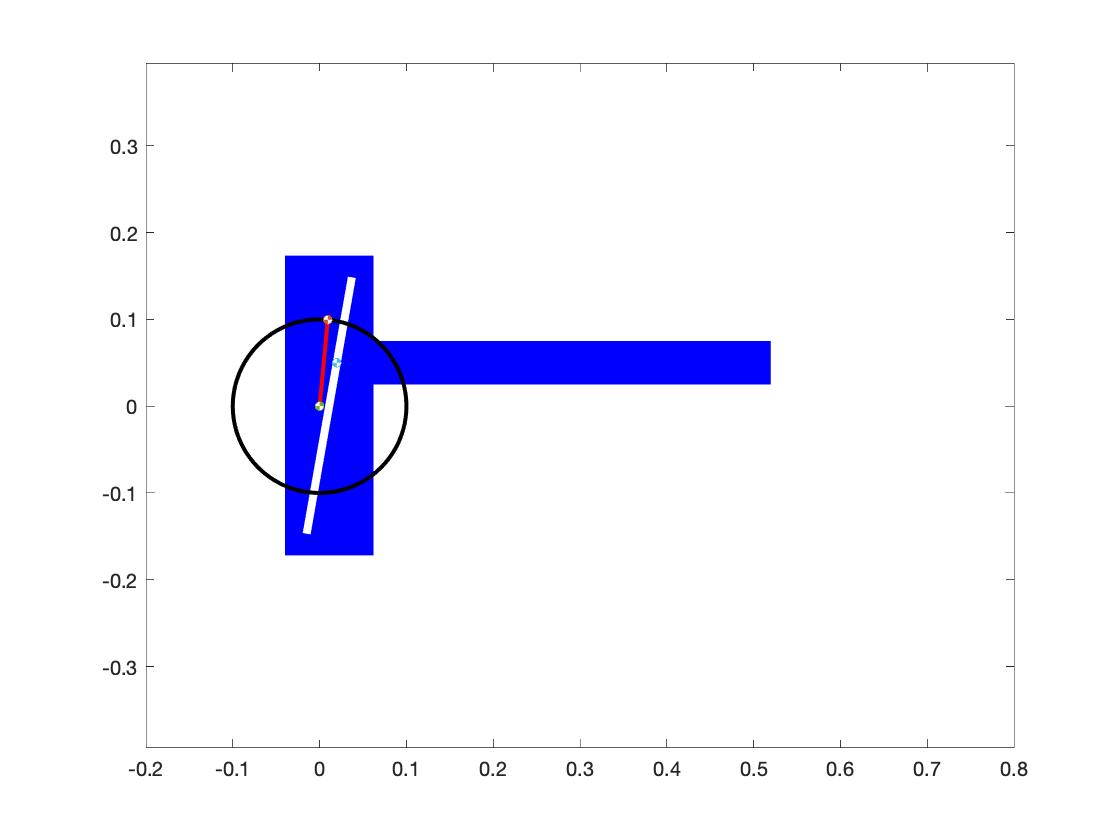

figure();
for k=1:10:size(p1,2)
  DAE.plot(p1(:,k));
  axis equal
  drawnow;
end

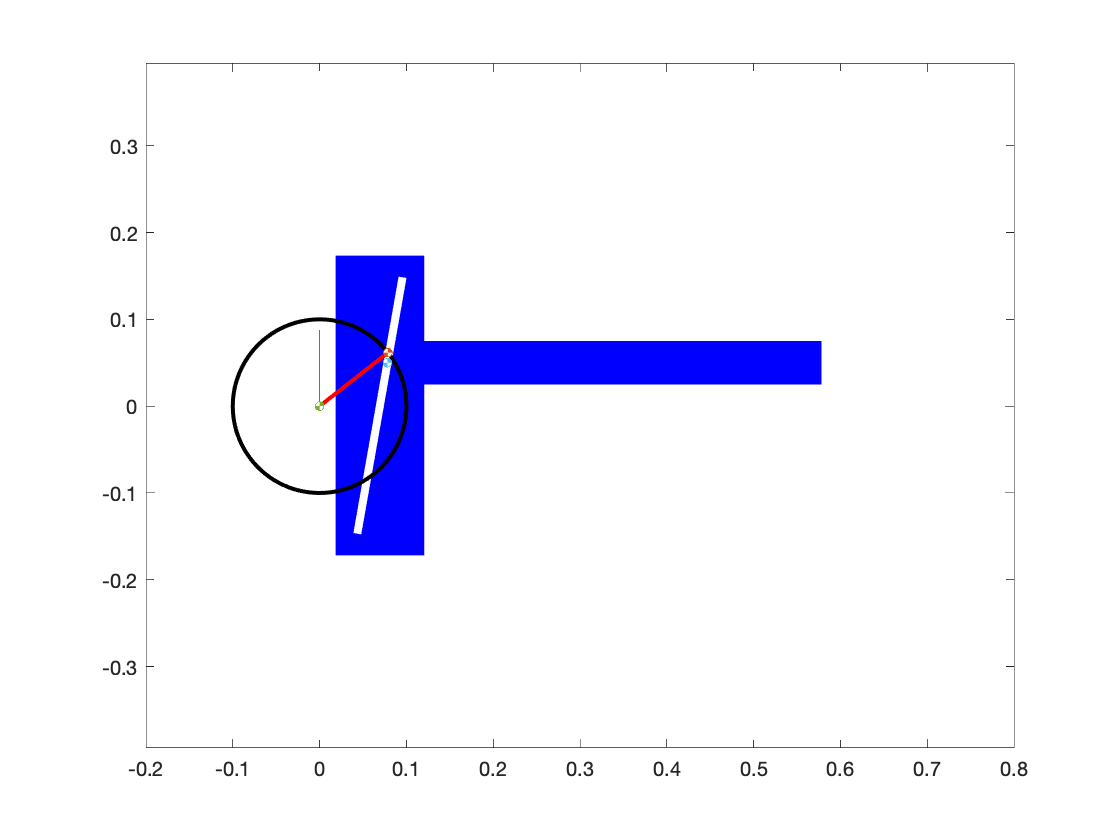

figure();
for k=1:10:size(p2,2)
  DAE.plot(p2(:,k));
  axis equal
  drawnow;
end